The goal is to study the effects of radiation pressure on a 9U satellite with large solar panels.

area = 1;       % m2
ref = 0.08;     % NA
initMass = 10;  % kg
endMass = 8;    % kg
isp = 2150;     % s
g0 = 9.80665;   % m/s2
exhVel = isp * g0;
thrust = 0.001; % N
mDot = 52e-9;   % kg/s

No propulsion will be needed.

burnOverride = -1;
thrustingThreshold = 1;

Set the orbit's intial conditions.

earthRadius = 6378136.3;    % m
[sma,ecc,inc,RAAN,aop,true_an] = deal(24371e3, 0.73, 5, 0, 135, -20);   % GTO
startDate = juliandate(datetime(2024, 01, 01));

Now choose a simulation length and run it.

tf = 6; tf = tf * 30 * 24 * 3600;
tic;
simOutSRP = sim('propagatorMain.slx');

### Building the rapid accelerator target for model: propagatorMain
### Successfully built the rapid accelerator target for model: propagatorMain

Build Summary

Top model rapid accelerator targets built:

Model           Action                        Rebuild Reason                                    
propagatorMain  Code generated and compiled.  Code generation information file does not exist.  

1 of 1 models built (0 models already up to date)
Build duration: 0h 0m 30.652s


toc

Elapsed time is 37.118741 seconds.


We extract the data from the simulation. For this, we only care about the position and velocity.

tsSatSRP = simOutSRP.yout{1}.Values;
ttSatSRP = timeseries2timetable(tsSatSRP);
tsSatVelSRP = simOutSRP.yout{2}.Values;
ttSatVelSRP  = timeseries2timetable(tsSatVelSRP);

To avoid conflicts with the viewer's trajectory representation, we retime the timetables manually.

ttSatSRP = retime(ttSatSRP,'minutely');
ttSatVelSRP = retime(ttSatVelSRP, 'minutely');

To use the same Simulink model for no solar radiation pressure, we just set the area of the satellite to 0.

area = 0;

And now run the simulation again.

tic;
simOutNoSRP = sim('propagatorMain.slx');


Build Summary

0 of 1 models built (1 models already up to date)
Build duration: 0h 0m 1.3927s


toc

Elapsed time is 5.455430 seconds.


Again extract the data and retime it.

tsSatNoSRP = simOutNoSRP.yout{1}.Values;
ttSatNoSRP = timeseries2timetable(tsSatNoSRP);
ttSatNoSRP = retime(ttSatNoSRP,'minutely');
tsSatVelNoSRP = simOutNoSRP.yout{2}.Values;
ttSatVelNoSRP  = timeseries2timetable(tsSatVelNoSRP);
ttSatVelNoSRP = retime(ttSatVelNoSRP, 'minutely');

Raw plot.

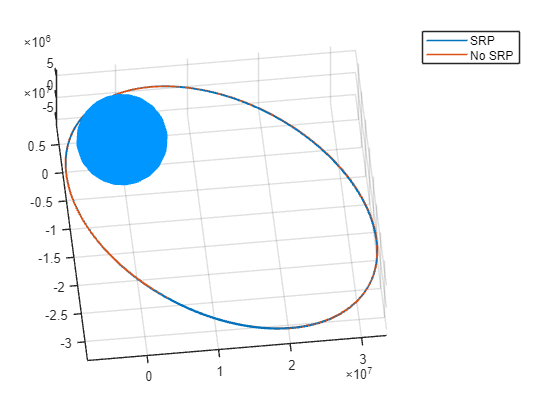

tic
figure
[X,Y,Z] = sphere();
p = surf(X*earthRadius, Y*earthRadius, Z*earthRadius); % plot Earth at the centre
set(p, 'edgecolor', 'none', 'FaceColor', [0,150,255]./255, 'HandleVisibility', 'off')
hold on
plot3(ttSatSRP.Data(:,1), ttSatSRP.Data(:,2), ttSatSRP.Data(:,3), DisplayName='SRP')
plot3(ttSatNoSRP.Data(:,1), ttSatNoSRP.Data(:,2), ttSatNoSRP.Data(:,3), DisplayName='No SRP')
legend
axis equal
daspect([1 1 1])
view([-6 52])

As a final check, we calculate the final orbital elements of both satellites.

r = ttSatNoSRP(1,1).Data;
v = ttSatVelNoSRP(1,1).Data;
[sma1,ecc1,inc1,RAAN1,aop1] = state2class(r, v, 1)

sma1 = 2.4371e+07

ecc1 = 0.7300

inc1 = 5.0000

RAAN1 = 360

aop1 = 135.0000

r = ttSatNoSRP(end,end).Data;
v = ttSatVelNoSRP(end,end).Data;
[sma2,ecc2,inc2,RAAN2,aop2] = state2class(r, v, 1)

sma2 = 2.4371e+07

ecc2 = 0.7281

inc2 = 4.6588

RAAN2 = 5.9166

aop2 = 129.3832

r = ttSatSRP(end,end).Data;
v = ttSatVelSRP(end,end).Data;
[sma3,ecc3,inc3,RAAN3,aop3] = state2class(r, v, 1)

sma3 = 2.4371e+07

ecc3 = 0.7291

inc3 = 4.6546

RAAN3 = 5.9855

aop3 = 129.2549

We can calculate the deviations between the two.

smaDev = (sma2-sma3)

smaDev = 43.3627

eccDev = (ecc2-ecc3)

eccDev = -0.0010

incDev = (inc2-inc3)

incDev = 0.0042

RAANDev = (RAAN2-RAAN3)

RAANDev = -0.0689

aopDev = (aop2-aop3)

aopDev = 0.1284